# Analysis of Robust Stability (RS) and Robust Performance (RP)

load statespace_data A B C D FWT

% 2 inputs, 2 outputs
s = tf('s');
G = FWT(1:2, 1:2);

% performance weights
wp = [(s/3+0.3*2*pi)/(s+pi*6e-5) 0;
    0 0.05];

wu = [0.005 0;
       0 (0.005*s^2 + 0.0007*s+0.00005)/(s^2 + 0.0014*s + 10^(-6))];

% uncertainty weights
wi1 = ((1/16*pi)*s + 0.3)/((1/64*pi)*s + 1);
wi2 = wi1;

wo1 = (0.05*s + 0.25)/(0.01*s + 1);
wo2 = wo1;

wi = [wi1 0;
      0 wi2];
wo = [wo1 0;
     0 wo2];

## 3. Frequency response of weights

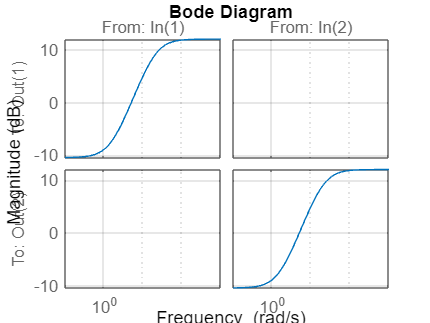

% frequency response of uncertainty weights
figure
bodemag(wi)
grid on

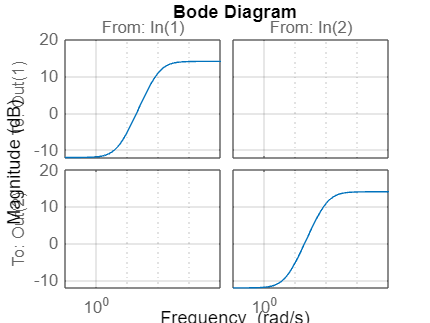


figure
bodemag(wo)
grid on

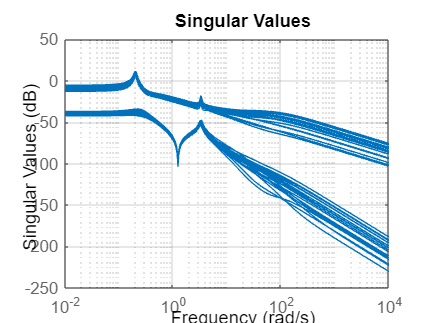


% uncertain TF singular values 

pb1 = ultidyn("idelta", 2);
pb2 = ultidyn("odelta", 2);

wid = wi*pb1;
wod = wo*pb2;

X = (eye(2)+wid)*G*(eye(2)+wod);

figure
sigma(X)
grid on

## 4. Augmented Generalised Plant

% Define plant and in- and outputs
G.u = 'udu';
G.y = 'y';

wp.u = 'v';
wp.y = 'z1';

wu.u = 'u';
wu.y = 'z2';

wo.u = 'y';
wo.y = 'do';

wi.u = 'u';
wi.y = 'di';

% Build system
sumblock1 = sumblk("ydy = y + dy", 2);
sumblock2 = sumblk("udu = u + du", 2);
sumblock3 = sumblk("v = w + ydy", 2);

dP = connect(G, wu, wp, wo, wi, sumblock1, sumblock2, sumblock3, {'du', 'dy', 'w', 'u'}, {'di', 'do', 'z1', 'z2', 'v'});

## 5. Checking NS, NP, RS, RP

load mixedsensitivitycontroller.mat MS_C P CLms Kfb_opt

K = MS_C;

% NS - generalised Nyquist
ol = K*G;
tdet = eye(2) - ol;

det = tdet(1,1)*tdet(2,2) - tdet(1,2)*tdet(2,1);

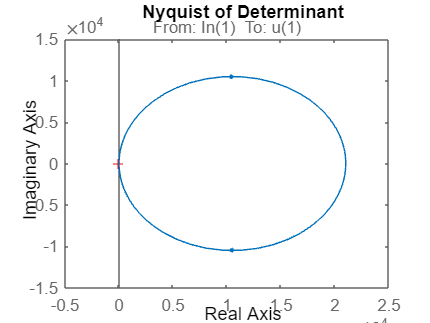


nyquist(det);
title('Nyquist of Determinant')


% NP - ||N||inf < 1
gamma = hinfnorm(CLms);

% RS
N = lft(dP, K);
M = N(1:4, 1:4);

% frequencies to check and shape of Delta block
omega=logspace(-3,4,1000);
Mf=frd(M,omega);
blockstructure =  ones(size(Mf,1),2);

% Calculate bounds over frequencies with blockstructure
[mubnds, muinfo] = mussv(Mf, blockstructure);

Points completed: 1000/1000



% norm of bound
muRS = mubnds(:,1);
[muRSinf, muRSw] = norm(muRS,inf);
muRSinf

muRSinf = 1.1505


% 
% Evaluate at frequencies and decide structure on uncertainty
Nf = frd(N,omega);
blockstructureN =  [blockstructure;
    2 4];

% Calculate bounds over frequencies with blockstructure
[mubnds, muinfo] = mussv(Nf, blockstructureN);

Points completed: 1000/1000



% norm of bound
muRP = mubnds(:,1);
[muRPinf, muRPw] = norm(muRP,inf);
muRPinf

muRPinf = 1.5529

# 2.2 Robust Controller Design

## 2.1 DK design

%D-K iterations

Delta=[ultidyn('D_1',[1,1]) 0 0 0; 0 ultidyn('D_2',[1,1]) 0 0; 0 0 ultidyn('D_3',[1,1]) 0; 0 0 0 ultidyn('D_4',[1,1])];

Punc=lft(Delta,dP);

[DK, clp, dkinfo]=musyn(Punc,2,2);



D-K ITERATION SUMMARY:
-----------------------------------------------------------------
                       Robust performance               Fit order
-----------------------------------------------------------------
  Iter         K Step       Peak MU       D Fit             D
    1           12.78        9.344        9.442            22
    2           6.671        6.577        6.622            16
    3           2.541        2.267        2.294            32
    4           1.319        1.317        1.336            30
    5           1.201          1.2        1.223            30
    6           1.175        1.175        1.192            36
    7           1.167        1.167        1.188            32
    8           1.162         1.16        1.181            34
    9           1.161         1.16        1.181            34

Best achieved robust performance: 1.16



## 2.2 Checking Performances of DK

% NS and NP

NS = max(real(eig(N)))

NS = -1.8850e-04


% NP - ||N||inf < 1
gamma_dk = hinfnorm(N)

% RS and RP
N = lft(dP, DK);
M = N(1:4, 1:4);

% frequencies to check and shape of Delta block
omega=logspace(-3,4,100);
Mf=frd(M,omega);
blockstructure =  -ones(size(Mf,1),2);

% Calculate bounds over frequencies with blockstructure
[mubnds, muinfo] = mussv(Mf, blockstructure);

Points completed: 100/100



% RS
muRS = mubnds(:,1);
[muRSinf, muRSw] = norm(muRS,inf);
muRSinf

muRSinf = 0.7970


% RP
% Evaluate at frequencies and decide structure on uncertainty
Nf = frd(N,omega);
blockstructureN =  [blockstructure;
    2 4];

% Calculate bounds over frequencies with blockstructure
[mubnds, muinfo] = mussv(Nf, blockstructureN);

Points completed: 100/100



% norm of bound
muRP = mubnds(:,1);
[muRPinf, muRPw] = norm(muRP,inf);
muRPinf

muRPinf = 1.1535

## 3. Time-domain Simulations

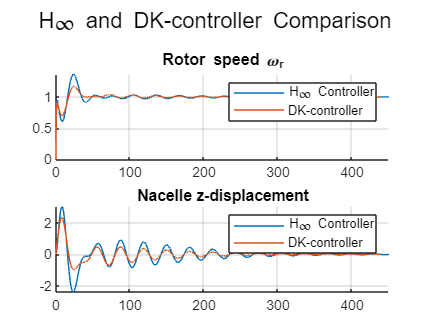

% H infinity Controller
CLstep_hinf = feedback(-MS_C*G, eye(2));

[y, tout] = step(CLstep_hinf);

% Fixed-structure Controller
CL_fs = feedback(-Kfb_opt*G, eye(2));

[y_fs, tout_fs] = step(CL_fs);


% DK controller
CL_dk = feedback(-DK*G, eye(2));

[y_dk, tout_dk] = step(CL_dk);

% figure
% step(CLstep_hinf)
% title('Step response using Generalised Controller')
% grid on
% 
% figure
% step(CL_dk)
% title('Step response using DK-controller')
% grid on

% DK vs Hinf
figure
subplot(2,1,1)
hold on
plot(tout, y(:,1,1))
plot(tout_dk, y_dk(:,1,1))
legend('H\infty Controller', 'DK-controller')
xlim([0, 450])
title('Rotor speed \omega_r')
grid on

subplot(2,1,2)
hold on
plot(tout, y(:,2,1))
plot(tout_dk, y_dk(:,2,1))
legend('H\infty Controller', 'DK-controller')
xlim([0, 450])
title('Nacelle z-displacement')
grid on

sgtitle('H\infty and DK-controller Comparison')

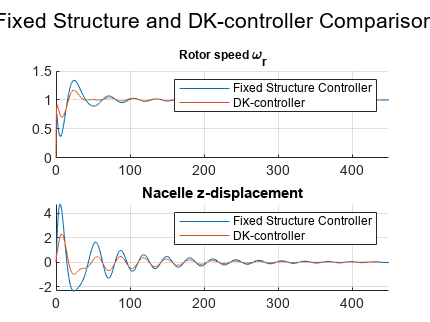


% DK vs FS
figure
subplot(2,1,1)
hold on
plot(tout_fs, y_fs(:,1,1))
plot(tout_dk, y_dk(:,1,1))
legend('Fixed Structure Controller', 'DK-controller')
xlim([0, 450])
title('Rotor speed \omega_r')
grid on

subplot(2,1,2)
hold on
plot(tout_fs, y_fs(:,2,1))
plot(tout_dk, y_dk(:,2,1))
legend('Fixed Structure Controller', 'DK-controller')
xlim([0, 450])
title('Nacelle z-displacement')
grid on

sgtitle('Fixed Structure and DK-controller Comparison')